
%% Exercise 1: Pixels and Quantization

% Load image and print properties
I = imread('cameraman.tif');
fprintf('Image size: %d x %d\n', size(I,1), size(I,2));

Image size: 256 x 256


fprintf('Image class: %s\n', class(I));

Image class: uint8


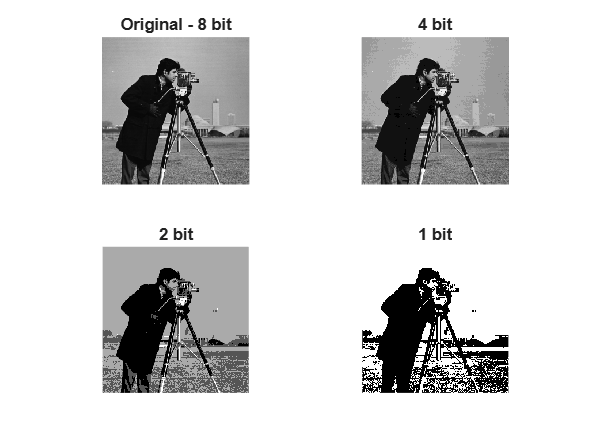


% Quantize to 4, 2 and 1 bit
I4 = uint8(round(double(I)/255*15)/15*255);
I2 = uint8(round(double(I)/255*3)/3*255);
I1 = uint8(round(double(I)/255)*255);

figure;
subplot(2,2,1); imshow(I); title('Original - 8 bit');
subplot(2,2,2); imshow(I4); title('4 bit');
subplot(2,2,3); imshow(I2); title('2 bit');
subplot(2,2,4); imshow(I1); title('1 bit');

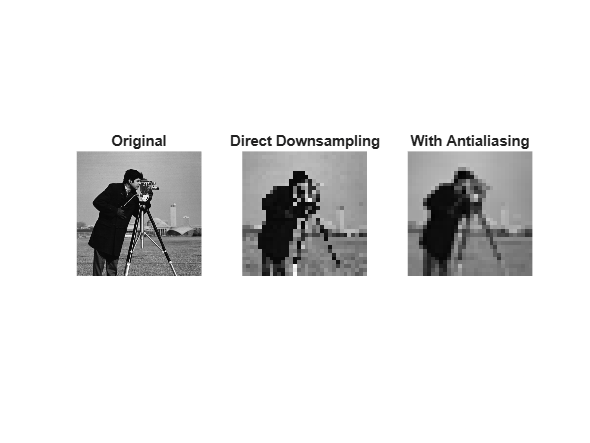


% Downsample by a factor of 8
I_direct = I(1:8:end, 1:8:end);
I_resize = imresize(I, 1/8, 'bicubic', ...
    'Antialiasing', true);

figure;
subplot(1,3,1); imshow(I); title('Original');
subplot(1,3,2); imshow(I_direct); title('Direct Downsampling');
subplot(1,3,3); imshow(I_resize); title('With Antialiasing');


fprintf('Downsampled size: %d x %d\n', ...
    size(I_direct,1), size(I_direct,2));

Downsampled size: 32 x 32


**Exercise 1 – Think About**

**1. At which bit depth do you stop recognizing the image?**

At 4 bits, the image is clear. At 2 bits, details are reduced. At 1 bit, the image becomes difficult to recognize.

**2. Where does aliasing become visible?**

Aliasing is more noticeable in the directly downsampled image, especially around fine details and sharp edges. Antialiasing reduces these artifacts.

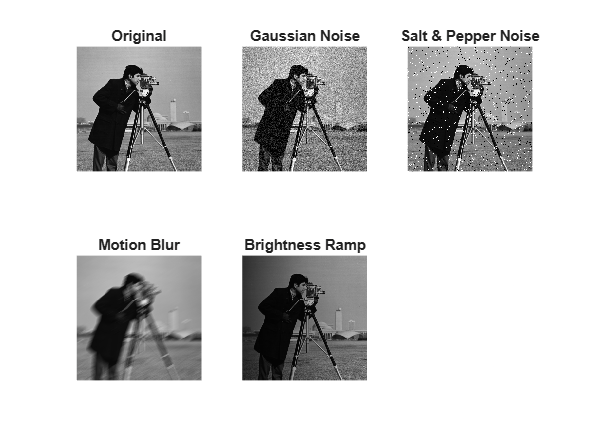


%% Exercise 2: Degrade an Image

% Load original image
I = im2double(imread('cameraman.tif'));

% 1. Gaussian noise (variance = 0.01)
I_gaussian = imnoise(I, 'gaussian', 0, 0.01);

% 2. Salt and pepper noise (density = 0.05)
I_sp = imnoise(I, 'salt & pepper', 0.05);

% 3. Motion blur (length = 15, angle = 30)
H = fspecial('motion', 15, 30);
I_motion = imfilter(I, H, 'replicate');

% 4. Multiplicative brightness ramp
[rows, cols] = size(I);
ramp = repmat(linspace(0.3, 1, cols), rows, 1);
I_ramp = I .* ramp;

% Display the original and degraded images
figure;

subplot(2,3,1);
imshow(I);
title('Original');

subplot(2,3,2);
imshow(I_gaussian);
title('Gaussian Noise');

subplot(2,3,3);
imshow(I_sp);
title('Salt & Pepper Noise');

subplot(2,3,4);
imshow(I_motion);
title('Motion Blur');

subplot(2,3,5);
imshow(I_ramp);
title('Brightness Ramp');

**Exercise 2 – Think About**

**1. Which degradation is additive, and which is multiplicative?**

Gaussian noise is additive because random values are added to the pixel intensities. The brightness ramp is multiplicative because pixel values are multiplied by a brightness factor. Motion blur is a filtering operation, while salt-and-pepper noise randomly replaces pixel values.

**2. Which noise will the median filter fix?**

The median filter is particularly effective at removing salt-and-pepper noise because it removes isolated black and white pixels while preserving edges.

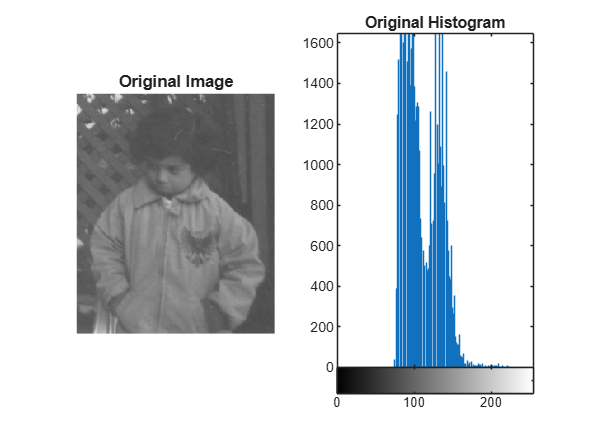


%% Exercise 3: Contrast and Geometry

% Load image
P = imread('pout.tif');

% Display original image and histogram
figure;
subplot(1,2,1);
imshow(P);
title('Original Image');

subplot(1,2,2);
imhist(P);
title('Original Histogram');

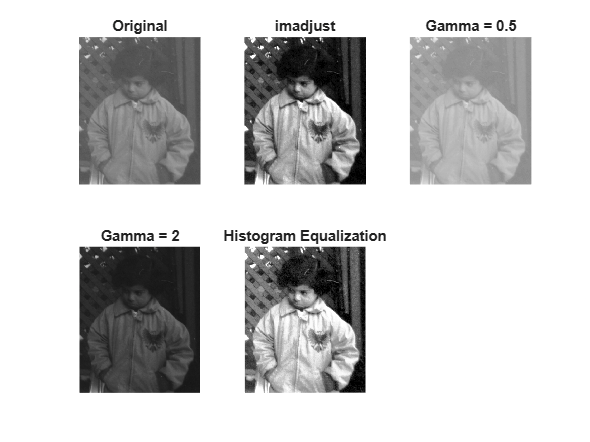


% Contrast adjustment
P_adjust = imadjust(P);

% Gamma correction
P_gamma05 = imadjust(P, [], [], 0.5);
P_gamma2 = imadjust(P, [], [], 2);

% Histogram equalization
P_histeq = histeq(P);

% Compare contrast methods
figure;

subplot(2,3,1);
imshow(P);
title('Original');

subplot(2,3,2);
imshow(P_adjust);
title('imadjust');

subplot(2,3,3);
imshow(P_gamma05);
title('Gamma = 0.5');

subplot(2,3,4);
imshow(P_gamma2);
title('Gamma = 2');

subplot(2,3,5);
imshow(P_histeq);
title('Histogram Equalization');

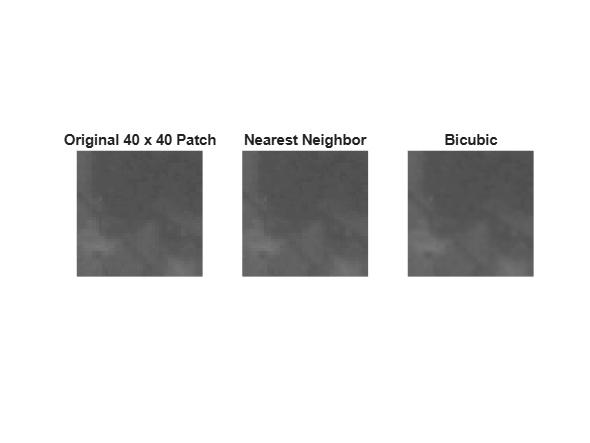


% Select a 40 x 40 patch
patch = P(60:99, 60:99);

% Enlarge patch by a factor of 8
P_nearest = imresize(patch, 8, 'nearest');
P_bicubic = imresize(patch, 8, 'bicubic');

% Compare interpolation methods
figure;

subplot(1,3,1);
imshow(patch);
title('Original 40 x 40 Patch');

subplot(1,3,2);
imshow(P_nearest);
title('Nearest Neighbor');

subplot(1,3,3);
imshow(P_bicubic);
title('Bicubic');

**Exercise 3 – Think About**

**1. Which method looks best?**

For contrast enhancement, `imadjust` generally produces a natural-looking result. For enlargement, bicubic interpolation looks smoother than nearest neighbor.

**2. Why does gamma below 1 brighten the image?**

Gamma correction applies a power function to pixel intensities. When gamma is below 1, intensity values between 0 and 1 increase, making the image brighter.

**3. What does bicubic do that nearest neighbor does not?**

Bicubic interpolation calculates new pixel values using surrounding pixels, creating smoother transitions. Nearest neighbor copies the closest pixel, producing blocky edges.

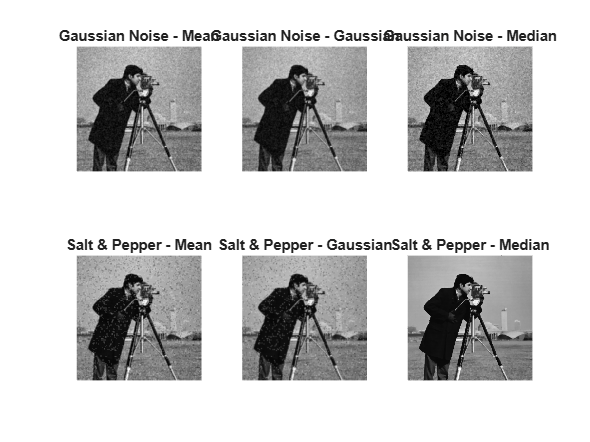


%% Exercise 4: Filter and Compare

% Load original image
I_original = im2double(imread('cameraman.tif'));

% Reuse I_gaussian and I_sp from Exercise 2

% Mean filter (3 x 3)
H_mean = fspecial('average', [3 3]);

G_mean = imfilter(I_gaussian, H_mean, 'replicate');
SP_mean = imfilter(I_sp, H_mean, 'replicate');

% Gaussian filter
G_gaussian = imgaussfilt(I_gaussian, 1);
SP_gaussian = imgaussfilt(I_sp, 1);

% Median filter
G_median = medfilt2(I_gaussian, [3 3]);
SP_median = medfilt2(I_sp, [3 3]);

% Display the six filtered images
figure;

subplot(2,3,1);
imshow(G_mean);
title('Gaussian Noise - Mean');

subplot(2,3,2);
imshow(G_gaussian);
title('Gaussian Noise - Gaussian');

subplot(2,3,3);
imshow(G_median);
title('Gaussian Noise - Median');

subplot(2,3,4);
imshow(SP_mean);
title('Salt & Pepper - Mean');

subplot(2,3,5);
imshow(SP_gaussian);
title('Salt & Pepper - Gaussian');

subplot(2,3,6);
imshow(SP_median);
title('Salt & Pepper - Median');


% Calculate PSNR against original image
PSNR_G = [
    psnr(G_mean, I_original);
    psnr(G_gaussian, I_original);
    psnr(G_median, I_original)
];

PSNR_SP = [
    psnr(SP_mean, I_original);
    psnr(SP_gaussian, I_original);
    psnr(SP_median, I_original)
];

% Create comparison table
Filter = {'Mean'; 'Gaussian'; 'Median'};

Results = table(Filter, PSNR_G, PSNR_SP, ...
    'VariableNames', ...
    {'Filter', 'GaussianNoise_dB', 'SaltPepperNoise_dB'});

disp('PSNR Comparison Table:');

PSNR Comparison Table:


disp(Results);

       Filter       GaussianNoise_dB    SaltPepperNoise_dB
    ____________    ________________    __________________

    {'Mean'    }         24.353               23.516      
    {'Gaussian'}         24.781               24.027      
    {'Median'  }         24.175               26.711      




% Find the best filter for each noise type
[~, bestG] = max(PSNR_G);
[~, bestSP] = max(PSNR_SP);

fprintf('Best for Gaussian noise: %s\n', Filter{bestG});

Best for Gaussian noise: Gaussian


fprintf('Best for salt & pepper noise: %s\n', Filter{bestSP});

Best for salt & pepper noise: Median


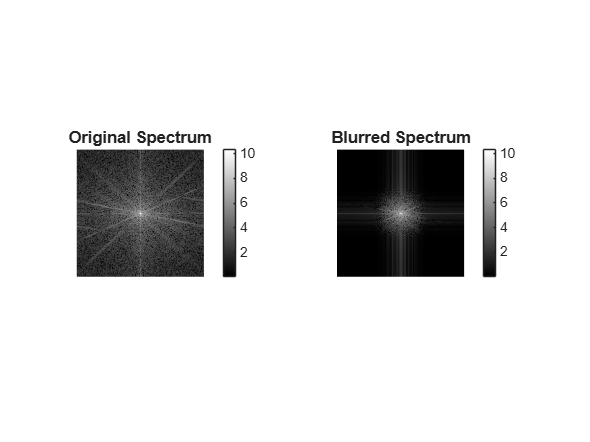


% Compare frequency spectra
I_blurred = imgaussfilt(I_original, 2);

F_original = fftshift(fft2(I_original));
F_blurred = fftshift(fft2(I_blurred));

figure;

subplot(1,2,1);
imagesc(log(1 + abs(F_original)));
axis image off;
colormap gray;
colorbar;
title('Original Spectrum');

subplot(1,2,2);
imagesc(log(1 + abs(F_blurred)));
axis image off;
colormap gray;
colorbar;
title('Blurred Spectrum');

**Exercise 4 – Think About**

**1. Which filter wins for which noise?**

According to the PSNR comparison, the best filter for Gaussian noise is [insert filter name], while the best filter for salt-and-pepper noise is [insert filter name]. The median filter is generally effective against salt-and-pepper noise.

**2. What changes in the spectrum when you blur?**

Blurring reduces high-frequency components, which represent fine details and sharp edges. The blurred image therefore has less high-frequency energy in its spectrum.

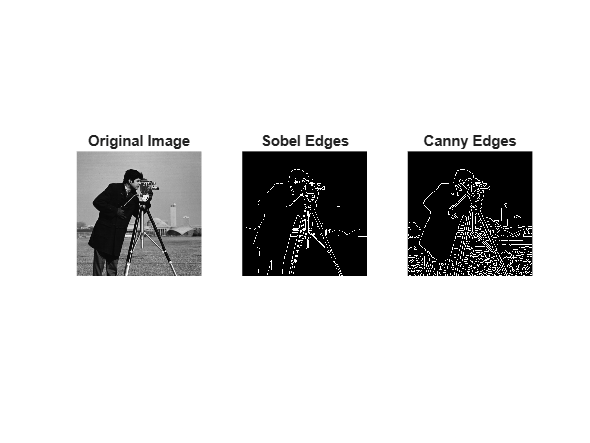


%% Exercise 5: Edge Detection

% Load original image
I = imread('cameraman.tif');

% 1. Sobel and Canny edge detection
E_sobel = edge(I, 'Sobel');
E_canny = edge(I, 'Canny');

figure;
subplot(1,3,1);
imshow(I);
title('Original Image');

subplot(1,3,2);
imshow(E_sobel);
title('Sobel Edges');

subplot(1,3,3);
imshow(E_canny);
title('Canny Edges');

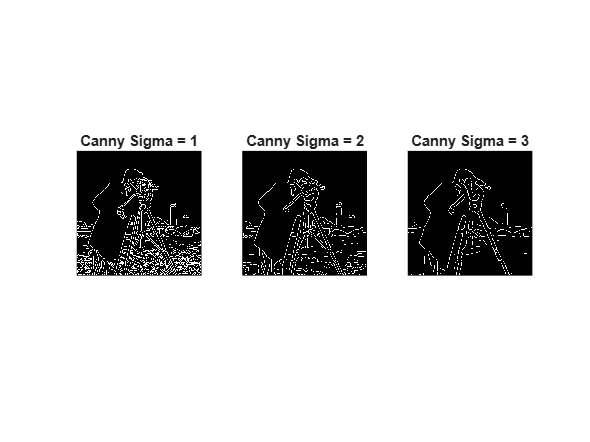


% 2. Compare different Canny sigma values
E_sigma1 = edge(I, 'Canny', [], 1);
E_sigma2 = edge(I, 'Canny', [], 2);
E_sigma3 = edge(I, 'Canny', [], 3);

figure;
subplot(1,3,1);
imshow(E_sigma1);
title('Canny Sigma = 1');

subplot(1,3,2);
imshow(E_sigma2);
title('Canny Sigma = 2');

subplot(1,3,3);
imshow(E_sigma3);
title('Canny Sigma = 3');


% 3. Edge detection on noisy image
% Reuse Gaussian noise from Exercise 2
I_noisy = I_gaussian;

% Smooth the noisy image
I_smoothed = imgaussfilt(I_noisy, 2);

% Apply Canny edge detection
E_noisy = edge(I_noisy, 'Canny');
E_smoothed = edge(I_smoothed, 'Canny');

% Count detected edge pixels
count_noisy = nnz(E_noisy);
count_smoothed = nnz(E_smoothed);

difference = count_noisy - count_smoothed;

fprintf('Edges without smoothing: %d\n', count_noisy);

Edges without smoothing: 13611


fprintf('Edges with smoothing: %d\n', count_smoothed);

Edges with smoothing: 4500


fprintf('Difference in edge pixels: %d\n', difference);

Difference in edge pixels: 9111


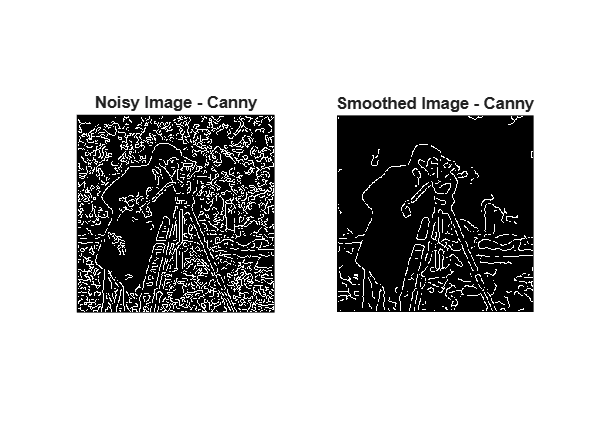


% Display the comparison
figure;
subplot(1,2,1);
imshow(E_noisy);
title('Noisy Image - Canny');

subplot(1,2,2);
imshow(E_smoothed);
title('Smoothed Image - Canny');

**Exercise 5 – Think About**

**1. How does sigma change the edge map?**

Increasing sigma produces stronger smoothing, reducing small details and noise. However, some fine edges may disappear when sigma becomes larger.

**2. How many false edges does smoothing remove?**

Before smoothing, Canny detected [first count] edge pixels. After smoothing, it detected [second count] pixels. The difference was [difference] pixels. This reduction suggests fewer noise-related edges, although some genuine edges may also be removed.


%% Exercise 6: Segment and Measure

% Load the image
C = imread('coins.png');

% Convert to grayscale if needed
if size(C,3) == 3
    C = rgb2gray(C);
end

% 1. Otsu thresholding
level = graythresh(C);
BW = imbinarize(C, level);

% 2. Clean the binary mask
BW_open = imopen(BW, strel('disk', 2));
BW_fill = imfill(BW_open, 'holes');
BW_clean = bwareaopen(BW_fill, 50);

% 3. Label connected components
[L, numCoins] = bwlabel(BW_clean);

% 4. Measure coin areas
stats = regionprops(L, 'Area');
areas = [stats.Area]';

% Print number of coins
fprintf('Number of detected coins: %d\n', numCoins);

Number of detected coins: 10



% Create area table
CoinID = (1:numCoins)';

CoinTable = table(CoinID, areas, ...
    'VariableNames', {'Coin', 'Area_pixels'});

disp('Coin Area Measurements:');

Coin Area Measurements:


disp(CoinTable);

    Coin    Area_pixels
    ____    ___________

      1        2651    
      2        1852    
      3        2641    
      4        2745    
      5         555    
      6        2510    
      7        2583    
      8        2544    
      9        1893    
     10        1864    




% Find the largest coin
[largestArea, largestID] = max(areas);

fprintf('Largest coin: %d\n', largestID);

Largest coin: 4


fprintf('Largest area: %.0f pixels\n', largestArea);

Largest area: 2745 pixels


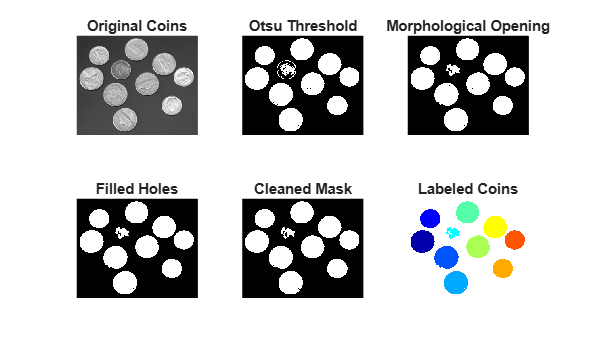


% Display segmentation steps
figure;
set(gcf, 'Position', [100 100 1200 700]);

subplot(2,3,1);
imshow(C);
title('Original Coins');

subplot(2,3,2);
imshow(BW);
title('Otsu Threshold');

subplot(2,3,3);
imshow(BW_open);
title('Morphological Opening');

subplot(2,3,4);
imshow(BW_fill);
title('Filled Holes');

subplot(2,3,5);
imshow(BW_clean);
title('Cleaned Mask');

subplot(2,3,6);
imshow(label2rgb(L));
title('Labeled Coins');

**Exercise 6 – Think About**

**1. Which step removed which artifact?**

Morphological opening removes small foreground noise and smooths object boundaries. `imfill` fills holes inside the coins, while `bwareaopen` removes remaining small objects.

**2. Which coin is the largest?**

According to the area measurements, coin [insert coin ID] is the largest, with an area of [insert area] pixels.

**3. Do touching coins merge?**

Yes. Touching coins can merge into one connected component if their binary regions are connected. The current method does not separate touching coins.